EULER EXPLÍCITO EN 2 DIMENSIONES

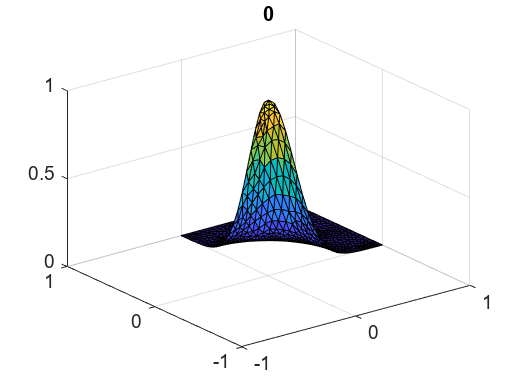

%------ PROBLEMA PARABÓLICO -----------%
%
% Tt = Dt*laplaciano(T) + at*(1-T/kt)*T - alphatn*N*T
% Nt = Dn*laplaciano(N) + an*(1-N/kn)*N - alphant*N*T
% dT/dn(fron) = 0
% dN/dn(fron) = 0
% T(x,0) = T0
% N(x,0) = N0
%
%------ discretización: euler explícito -------%
%
% T_n+1 = T_n + dt*(Dt*lap(T_n) + at*(1-T_n/kt)*T_n - alphatn*N_n*T_n)
%
% M*T_n+1 = ((1+dt*at)*M - dt*Dt*R)*T_n - dt*an/kn*M*z_n - dt*alphatn*M*w_n
%
% idem para N_n+1

% load('mallado_tumor.mat')

%parametros de la EDP
an = 8.64e-7;   %[1/día]
at = 1.2e-2;    %[1/día]
Dn = 2.0e-15;   %[cm^2/día]
Dt = 4.2e-3;    %[cm^2/día]
kn = 1;
kt = 1;
alpha_tn = 1.0e-4;   %[1/día]
alpha_nt = 1.0e-4;   %[1/día]

%parametros en el tiempo
dt = 0.01;
t0 = 0;
tf = 100;
Nt = (tf - t0) / dt;

%para el mallado usamos pdetool
%load('mallado_tumor.mat')
xi = p(1,:);
yi = p(2,:);
elem = t(1:3,:)'; %transponemos para usar el comando trisurf
%frontera de D
fron = unique([e(1,:) e(2,:)]);

%assema calcula las matrices de rigidez y de masas
[R M] = assema(p,t,1,1,0);

%condiciones iniciales de las variables
T0 = @(x,y) exp(-(x.^2+y.^2)*10);
Thn = T0(xi,yi)';
Nhn = 1 - T0(xi,yi)';
whn = Thn .* Nhn;
z_thn = Thn.^2;
z_nhn = Nhn.^2;
figure(1)
trisurf(elem,xi,yi,Thn);
title(0)
% view(2)
% shading interp
% colorbar
% caxis([-0.1 0.1])
axis([-1 1 -1 1 0 1])

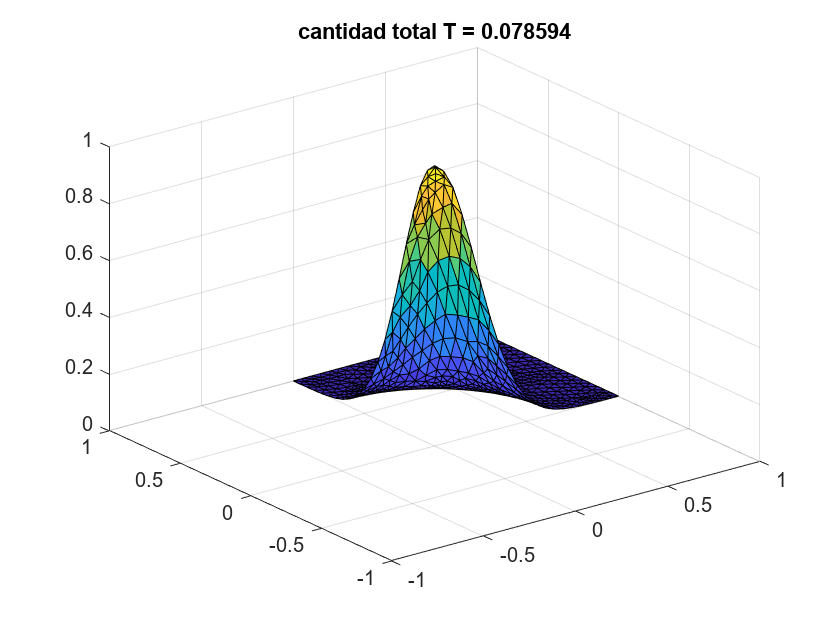

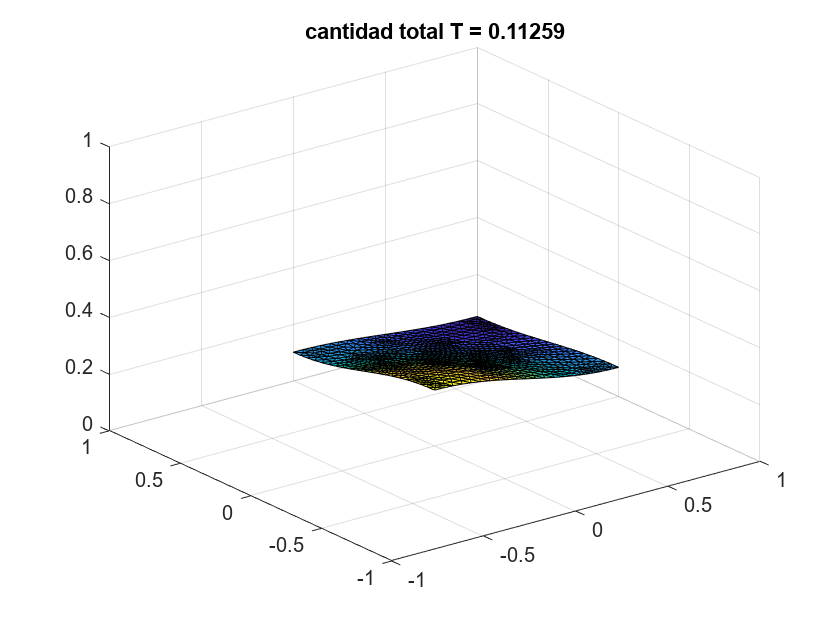

pause(1e-10)
for n = 1:Nt
    vect_b_t = ((1+dt*at)*M - dt*Dt*R)*Thn -dt*at/kt*M*z_thn - dt*alpha_tn*M*whn;
    vect_b_n = ((1+dt*an)*M - dt*Dn*R)*Nhn -dt*an/kn*M*z_nhn - dt*alpha_nt*M*whn;
    
    Thn = M\vect_b_t;
    Nhn = M\vect_b_n;

    whn = Thn .* Nhn;
    z_thn = Thn.^2;
    z_nhn = Nhn.^2;    

    T = 0;
    N = 0;

    if mod(n,10) == 0

              for j=1:length(t) 
                    
                    n1=t(1,j);
                    n2=t(2,j);
                    n3=t(3,j);
                
                    Atra=[p(1,n2)-p(1,n1) p(1,n3)-p(1,n1);p(2,n2)-p(2,n1) p(2,n3)-p(2,n1)];
                    F = @(x,y) Atra*[x;y]+[p(1,n1);p(1,n1)];
                    
                    w1=0.5*(1/3);
                    w2=w1;
                    w3=w1;
                    
                    p1 = F(0,0);
                    p2 = F(1,0);
                    p3 = F(0,1);
                    
                    T=T+det(Atra)*(w1*Thn(n1)+w2*Thn(n2)+w3*Thn(n3)); 
                    N=N+det(Atra)*(w1*Nhn(n1)+w2*Nhn(n2)+w3*Nhn(n3)); 
                    
               end                    


        figure(1)
        trisurf(elem,xi,yi,Thn)
        
        title(['cantidad total T = ', num2str(T)]);
    %     view(2)
    %     shading interp
    %     colorbar
    %     caxis([-0.1 0.1])
        axis([-1 1 -1 1 0 1])
        pause(1e-10)
    end
end

EULER MEJORADO EN 2 DIMENSIONES

%------ PROBLEMA PARABÓLICO -----------%
%
% Tt = Dt*laplaciano(T) + at*(1-T/kt)*T - alphatn*N*T
% Nt = Dn*laplaciano(N) + an*(1-N/kn)*N - alphant*N*T
% dT/dn(fron) = 0
% dN/dn(fron) = 0
% T(x,0) = T0
% N(x,0) = N0
%
%------ discretización: euler mejorado -------%
%
% K_T = T_n + dt*(Dt*lap(T_n) + at*(1-T_n/kt)*T_n - alphatn*N_n*T_n)
%
% T_n+1 = T_n + dt*(Dt*lap(K_T) + at*(1-K_T/kt)*K_T - alphatn*K_N*K_T)
%
% M*T_n+1 = ((1+dt*at)*M - dt*Dt*R)*K_T - dt*an/kn*M*z_n - dt*alphatn*M*w_n
%
% idem para N_n+1

%load('mallado_tumor.mat')

%parametros de la EDP
an = 8.64e-7;   %[1/día]
at = 1.2e-2;    %[1/día]
Dn = 2.0e-15;   %[cm^2/día]
Dt = 4.2e-3;    %[cm^2/día]
kn = 1;
kt = 1;
alpha_tn = 1.0e-4;   %[1/día]
alpha_nt = 1.0e-4;   %[1/día]

%parametros en el tiempo
dt = 0.01;
t0 = 0;
tf = 100;
Nt = (tf - t0) / dt;

%para el mallado usamos pdetool
%load('mallado_tumor.mat')
xi = p(1,:);
yi = p(2,:);
elem = t(1:3,:)'; %transponemos para usar el comando trisurf
%frontera de D
fron = unique([e(1,:) e(2,:)]);

%assema calcula las matrices de rigidez y de masas
[R M] = assema(p,t,1,1,0);

%condiciones iniciales de las variables
T0 = @(x,y) exp(-(x.^2+y.^2)*10);
Thn = T0(xi,yi)';
Nhn = 1 - T0(xi,yi)';
whn = Thn .* Nhn;
z_thn = Thn.^2;
z_nhn = Nhn.^2;
figure(1)
trisurf(elem,xi,yi,Thn);
title(0)
% view(2)
% shading interp
% colorbar
% caxis([-0.1 0.1])
axis([-1 1 -1 1 0 1])
pause(1e-10)
for n = 1:Nt
    vect_k_t = ((1+dt*at)*M - dt*Dt*R)*Thn -dt*at/kt*M*z_thn - dt*alpha_tn*M*whn;
    vect_k_n = ((1+dt*an)*M - dt*Dn*R)*Nhn -dt*an/kn*M*z_nhn - dt*alpha_nt*M*whn;
    
    K_T = M\vect_k_t;
    K_N = M\vect_k_n;

    whn = K_T .* K_N;
    z_thn = K_T.^2;
    z_nhn = K_N.^2;

    vect_b_t = ((1+dt*at)*M - dt*Dt*R)*K_T -dt*at/kt*M*z_thn - dt*alpha_tn*M*whn;
    vect_b_n = ((1+dt*an)*M - dt*Dn*R)*K_N -dt*an/kn*M*z_nhn - dt*alpha_nt*M*whn;
    
    Thn = M\vect_b_t;
    Nhn = M\vect_b_n;

    whn = Thn .* Nhn;
    z_thn = Thn.^2;
    z_nhn = Nhn.^2;    

    if mod(n,10) == 0
        figure(1)
        trisurf(elem,xi,yi,Thn)
        title('EULER MEJORADO EN 2 DIMENSIONES',n*dt)
    %     view(2)
    %     shading interp
    %     colorbar
    %     caxis([-0.1 0.1])
        axis([-1 1 -1 1 0 1])
        pause(1e-10)
    end
end

EULER EXPLÍCITO CON LAPLACIANO IMPLÍCITO

%------ PROBLEMA PARABÓLICO -----------%
%
% Tt = Dt*laplaciano(T) + at*(1-T/kt)*T - alphatn*N*T
% Nt = Dn*laplaciano(N) + an*(1-N/kn)*N - alphant*N*T
% dT/dn(fron) = 0
% dN/dn(fron) = 0
% T(x,0) = T0
% N(x,0) = N0
%
%------ discretización: euler explícito con laplaciano implícito -------%
%
% T_n+1 = T_n + dt*(0.5*Dt*(lap(T_n+1)+lap(T_n-1)) + at*(1-T_n/kt)*T_n - alphatn*N_n*T_n)
%
% M*T_n+1 = ((1+dt*at)*M - dt*Dt*R)*T_n - dt*an/kn*M*z_n - dt*alphatn*M*w_n
%
% idem para N_n+1

%Parámetros
an = 8.64e-7;   %[1/día]
at = 1.2e-2;    %[1/día]
Dn = 2.0e-15;   %[cm^2/día]
Dt = 4.2e-3;    %[cm^2/día]
kn = 1;
kt = 1;
alpha_tn = 1.0e-4;   %[1/día]
alpha_nt = 1.0e-4;   %[1/día]

%intervalo
dt=0.01;
t0=0;
tf=100;
Nt=(tf-t0)/dt;

xi=p(1,:);
yi=p(2,:);
elem=t(1:3,:)';
fron_d=unique([e(1,:) e(2,:)]); 

%matriz de masas y rigidez
[R M]=assema(p,t,1,1,0);

A_t = M+0.5*dt*Dt*R;
A_n = M+0.5*dt*Dn*R;


%condiciones iniciales

% T es la densidad de células tumorales
T0 = @(x,y) exp(-(x.^2+y.^2)*10);

Thn = T0(xi,yi)';
Nhn = 1 - T0(xi,yi)';

whn = Thn .* Nhn;
z_thn = Thn.^2;
z_nhn = Nhn.^2;

trisurf(elem,xi,yi,Thn)
title('Concentración células tumorales en t=0')
pause(1e-10)

%valores en tiempo n-1
Thnn=Thn;
Nhnn=Nhn;

%Primera iteración con EULER EXPLÍCITO
%Hago esta aprimera iteración con Euler explícito para tener términos n y
%que los valores en t0 sean los n-1
vect_b_t = ((1+dt*at)*M - dt*Dt*R)*Thn -dt*at/kt*M*z_thn - dt*alpha_tn*M*whn;
vect_b_n = ((1+dt*an)*M - dt*Dn*R)*Nhn -dt*an/kn*M*z_nhn - dt*alpha_nt*M*whn;

Thn = M\vect_b_t;
Nhn = M\vect_b_n;

whn = Thn .* Nhn;
z_thn = Thn.^2;
z_nhn = Nhn.^2;

trisurf(elem,xi,yi,Thn)
title(dt)
pause(1e-10)

%ahora es con el laplaciano implícito
for n=2:Nt
    vect_t=(1+at*dt)*M*Thn-dt*at/kt*M*z_thn-dt*alpha_tn*M*whn-dt*Dt*0.5*R*Thnn; 
    vect_n=(1+an*dt)*M*Nhn-dt*at/kn*M*z_nhn-dt*alpha_tn*M*whn-dt*Dt*0.5*R*Nhnn;

    Thnn=Thn; %el el siguiente instante los T_n pasan a ser T_n-1
    Nhnn=Nhn;

    Thn=A_t\vect_t;  %en el siguiente instante los T_n+1 pasan a ser T_n
    Nhn=A_n\vect_n;

    whn = Thn .* Nhn;
    z_thn = Thn.^2;
    z_nhn = Nhn.^2;

    if mod(n,10) == 0
        figure(1)
        trisurf(elem,xi,yi,Thn)
        title('EULER EXPLÍCITO CON LAPLACIANO IMPLÍCITO',n*dt)
        %     view(2)
        %     shading interp
        %     colorbar
        %     caxis([-0.1 0.1])
        axis([-1 1 -1 1 0 1])
        pause(1e-10)
    end
end

CRANK-NICHOLSON + NEWTON-RAPHSON

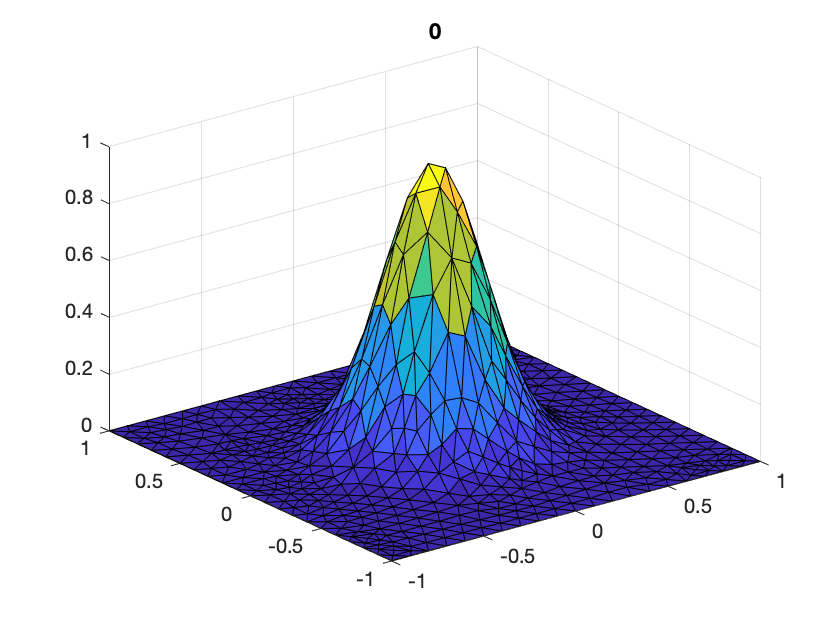

%------ PROBLEMA PARABÓLICO -----------%
%
% Tt = Dt*laplaciano(T) + at*(1-T/kt)*T - alphatn*N*T
% Nt = Dn*laplaciano(N) + an*(1-N/kn)*N - alphant*N*T
% dT/dn(fron) = 0
% dN/dn(fron) = 0
% T(x,0) = T0
% N(x,0) = N0
%
%------ discretización: crank-nicolson ---------%

%load('mallado_tumor.mat')

%parametros de la EDP
an = 8.64e-7;   %[1/día]
at = 1.2e-2;    %[1/día]
Dn = 2.0e-15;   %[cm^2/día]
Dt = 4.2e-3;    %[cm^2/día]
kn = 1;
kt = 1;
alpha_tn = 1.0e-4;   %[1/día]
alpha_nt = 1.0e-4;   %[1/día]

%parametros en el tiempo
dt = 0.1;
t0 = 0;
tf = 100;
Nt = (tf - t0) / dt;

%parametros de newton-raphson
N_newton = 10000;
delta = 1e-10;

%para el mallado usamos pdetool
%load('mallado_tumor.mat')
xi = p(1,:);
yi = p(2,:);
elem = t(1:3,:)'; %transponemos para usar el comando trisurf
%frontera de D
fron = unique([e(1,:) e(2,:)]);
Nn = length(xi); %numero de nodos

%assema calcula las matrices de rigidez y de masas
[R M] = assema(p,t,1,1,0);

%jacobiana  del sistema para newton-raphson
I = eye(Nn);
JF = @(X) [(1-0.5*dt*at)*M+0.5*dt*Dt*R,0*M,0.5*dt*at/kt*M,0*M,0.5*dt*alpha_tn*M;...
    0*M,(1-0.5*dt*an)*M+0.5*dt*Dn*R,0*M,0.5*dt*an/kn*M,0.5*dt*alpha_nt*M;...
    -2*diag(X(1:Nn)),0*M,I,0*M,0*M;...
    0*M,-2*diag(X(Nn+1:2*Nn)),0*M,I,0*M;...
    -diag(X(Nn+1:2*Nn)),-diag(X(1:Nn)),0*M,0*M,I];

%condiciones iniciales de las variables
T0 = @(x,y) exp(-(x.^2+y.^2)*10);
Thn = T0(xi,yi)';
Nhn = 1 - T0(xi,yi)';
whn = Thn .* Nhn;
z_thn = Thn.^2;
z_nhn = Nhn.^2;
figure(1)
trisurf(elem,xi,yi,Thn);
title(0)
% view(2)
% shading interp
% colorbar
% caxis([-0.1 0.1])
axis([-1 1 -1 1 0 1])

pause(1e-10)
for n = 1:Nt

    F = @(X) [M*((1-0.5*dt*at)*X(1:Nn)+0.5*dt*at/kt*X(2*Nn+1:3*Nn)+0.5*dt*alpha_tn*X(4*Nn+1:5*Nn))+R*X(1:Nn)*0.5*dt*Dt-M*((1+0.5*dt*at)*Thn-0.5*dt*at/kt*z_thn-0.5*dt*alpha_tn*whn)-R*Thn*0.5*dt*Dt;...
        M*((1-0.5*dt*an)*X(Nn+1:2*Nn)+0.5*dt*an/kn*X(3*Nn+1:4*Nn)+0.5*dt*alpha_nt*X(4*Nn+1:5*Nn))+R*X(Nn+1:2*Nn)*0.5*dt*Dn-M*((1+0.5*dt*an)*Nhn-0.5*dt*an/kn*z_nhn-0.5*dt*alpha_nt*whn)-R*Nhn*0.5*dt*Dn;...
        X(2*Nn+1:3*Nn)-X(1:Nn).^2;...
        X(3*Nn+1:4*Nn)-X(Nn+1:2*Nn).^2;...
        X(4*Nn+1:5*Nn)-X(1:Nn).*X(Nn+1:2*Nn)];
    Xn = [Thn;Nhn;z_thn;z_nhn;whn];
    for i = 1:N_newton
        Xn_ant = Xn;
        Xn = Xn - JF(Xn)\F(Xn);
        if norm(Xn-Xn_ant)/norm(Xn)<delta
            break;
        end
    end
    Thn = Xn(1:Nn);
    Nhn = Xn(Nn+1:2*Nn);
    z_thn = Xn(2*Nn+1:3*Nn);
    z_nhn = Xn(3*Nn+1:4*Nn);
    whn = Xn(4*Nn+1:5*Nn);

    if mod(n,1) == 0
        figure(1)
        trisurf(elem,xi,yi,Thn)
        title('CRANK NICHOLSON',n*dt)
        view(2)
        shading interp
        colorbar
        caxis([-0.1 0.1])
        axis([-1 1 -1 1 0 1])
        pause(1e-10)
    end
end


EULER EXPLÍCITO EN 3 DIMENSIONES

%------ PROBLEMA PARABÓLICO -----------%
%
% Tt = Dt*laplaciano(T) + at*(1-T/kt)*T - alphatn*N*T
% Nt = Dn*laplaciano(N) + an*(1-N/kn)*N - alphant*N*T
% dT/dn(fron) = 0
% dN/dn(fron) = 0
% T(x,0) = T0
% N(x,0) = N0
%
%------ discretización: euler explícito -------%
%
% T_n+1 = T_n + dt*(Dt*lap(T_n) + at*(1-T_n/kt)*T_n - alphatn*N_n*T_n)
%
% M*T_n+1 = ((1+dt*at)*M - dt*Dt*R)*T_n - dt*an/kn*M*z_n - dt*alphatn*M*w_n

%parametros de la EDP
an = 8.64e-7;   %[1/día]
at = 12;    %[1/día]
Dn = 2.0e-15;   %[cm^2/día]
Dt = 4.2e-3;    %[cm^2/día]
kn = 1;
kt = 1;
alpha_tn = 1.0e-4;   %[1/día]
alpha_nt = 1.0e-4;   %[1/día]

%parametros en el tiempo
dt = 0.1;
t0 = 0;
tf = 3;
Nt = (tf - t0) / dt;

myPDE = createpde;
importGeometry(myPDE,'Block.stl')
generateMesh(myPDE,'hmax',.2,'geometricorder','linear');

xi = myPDE.Mesh.Nodes(1,:);
yi = myPDE.Mesh.Nodes(2,:);
zi = myPDE.Mesh.Nodes(3,:);
elem = myPDE.Mesh.Elements';

%aunque no es así, decimos que todos los nodos de la frontera sean neumann (se usa para obtener Q)
applyBoundaryCondition(myPDE,'neumann','Face',1:6,'q',1) %6 caras
specifyCoefficients(myPDE,'a',1,'c',1,'m',0,'d',0,'f',0); %esto es siempre así
FEM_KM = assembleFEMatrices(myPDE,'none');

M = FEM_KM.A;
R = FEM_KM.K;
Mf  = FEM_KM.Q; %matriz de masas en la frontera

fron = find(diag(Mf)>0);
fron_d = find(xi==10);
fron_n = setdiff(fron, fron_d);

% condiciones iniciales de las variables
% Posiciones de las fuentes de tumor
centros_tumor = [3, 1, 3];
T0 = @(x, y, z) 0;
for i = 1:size(centros_tumor, 1)
    % Agregar ruido o deformación en la forma del tumor?
    T0 = @(x, y, z) T0(x, y, z) + exp(-((x - centros_tumor(i, 1)).^2 + (y - centros_tumor(i, 2)).^2 + (z - centros_tumor(i, 3)).^2));
end

Thn = T0(xi,yi,zi)';
Nhn = 1 - T0(xi,yi,zi)';
whn = Thn .* Nhn;
z_thn = Thn.^2;
z_nhn = Nhn.^2;

%graficas
% figure(1)
% pdegplot(myPDE,'Facelabels','on');
% title('Caras del cuerpo')
% figure(2)
% pdeplot3D(myPDE);
% title('myPDE')
% figure(3)
% pdeplot3D(myPDE,"ColorMapData",Thn);
% title('Color Map')
% axis equal
% pause(0.001)

% Crear una matriz para almacenar las soluciones
T_solutions = zeros(size(Thn, 1), Nt);  % Soluciones de T
N_solutions = zeros(size(Nhn, 1), Nt);  % Soluciones de N

%bucle temporal
for n = 1:Nt
    vect_b_t = ((1+dt*at)*M - dt*Dt*R)*Thn -dt*at/kt*M*z_thn - dt*alpha_tn*M*whn;
    vect_b_n = ((1+dt*an)*M - dt*Dn*R)*Nhn -dt*an/kn*M*z_nhn - dt*alpha_nt*M*whn;
    
    Thn = M\vect_b_t;
    Nhn = M\vect_b_n;
    
    % Almacenar las soluciones en cada instante
    T_solutions(:, n) = Thn;
    N_solutions(:, n) = Nhn;

    whn = Thn .* Nhn;
    z_thn = Thn.^2;
    z_nhn = Nhn.^2;    

    if mod(n,1) == 0
%         figure(3)
%         h = pdeplot3D(myPDE,"ColorMapData",Thn);
%         title(n)
%         axis equal
%         h.FaceAlpha = 0.5;
%         pause(0.001)
        figure(1)
        trisurf(elem, xi, yi, zi, Thn, 'FaceAlpha', 0.1);
        title('Concentración de tumor en el tiempo ',n)
        axis equal
        colorbar
%         figure(2)
%         trisurf(elem, xi, yi, zi, Nhn, 'FaceAlpha', 0.1);
%         title('Concentración de células sanas en el tiempo ',n)
%         axis equal
%         colorbar
        pause(0.001)
    end
end

% Guardar nodos, elementos y valores de la solución
save('soluciones_tumor.mat', 'T_solutions', 'N_solutions', 'xi', 'yi', 'zi');


%otros sofwares para ver la solucion: mayavi